clear all
format longG
close all

% %{   section 
                  %}
% ----> deactivating whole the section

%{
% Data point without gaussian-filter

data = xlsread("Re-analyze.xlsx");
ti = data(:,6);
yi = data(:,7);
V0 = data(8,1);
%}

%%{
% Normalization and Reducing data-points using gaussian-filter 
data = xlsread("Re-analyze.xlsx");
%ti = data(:,6);
raw_time = data(:,6);
raw_volume = data(:,7);
time = data(:,8);
volume = data(:,9);
time(isnan(time)) = [];
volume(isnan(volume)) = [];
V0 = data(8,1);
%tn = time./60;
%yn = volume./V0;
ti = smoothdata(time,"gaussian",1500);
yi = smoothdata(volume,"gaussian",1500);
ti(isnan(ti)) = [];
yi(isnan(yi)) = [];
%}

%{
p = plot(raw_time,raw_volume,'.','Color',[0 0.4470 0.7410],"MarkerSize",5);
hold on
p = plot(ti,yi,'*','Color',[0.6350 0.0780 0.1840],"MarkerSize",3);
legend('raw-data','smoothed_data','location','best');
axis([0 4 0.2 1.8]);
hold off
%}

R = data(1,1);
T = data(2,1);
Me = data(3,1);
Mn0i = data(4,1);
Vbf = data(5,1);
Vs0 = data(6,1);
Mse = data(7,1);
A=((36*pi)^(1/3))*((V0)^(2/3));

save variables R T A Me V0 A Vbf Me Mn0i Vs0 Mse ti yi raw_volume raw_time volume time

x0 = [0.1,40];
k = fminsearch('obj',x0);
Lp = k(1);
Ps = k(2);
LpPs = [k(1),k(2)] 

LpPs =           1.96864716416685          186.041128562369


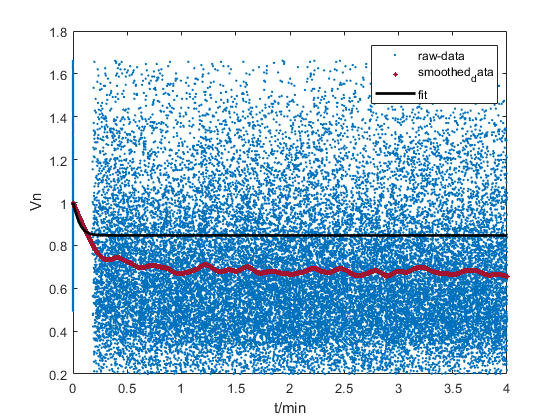

obj_plot(k);


% f = uifigure("Visible","on");
% fig = f;
% message = sprintf('Program is done');
% uialert(fig,message,'Warning','Icon','success','CloseFcn',@(h,e) close(f));